b_1 = [0.88184 -2.64551 2.64551 -0.88184]; a_1 = [1 -2.74884 2.52823 -0.77764];
b_2 = [0.77725 -2.33174 2.33174 -0.77725]; a_2 = [1 -2.49861 2.11525 -0.60411];
b_3 = [0.77725 -2.33174 2.33174 -0.77725]; a_3 = [0.60411 -2.11525 2.49861 -1];

F_s = 2.5e3;
dF = 0.25;

f_v = 0:dF:F_s/2-dF;
https://learn.inside.dtu.dk/d2l/lms/quizzing/user/attempt/quiz_start_frame_auto.d2l?ou=271239&isprv=&qi=33996&cfql=0&dnb=0&fromQB=0&inProgress=0
F_s/2

ans = 1250

max(f_v)

ans = 1.2498e+03

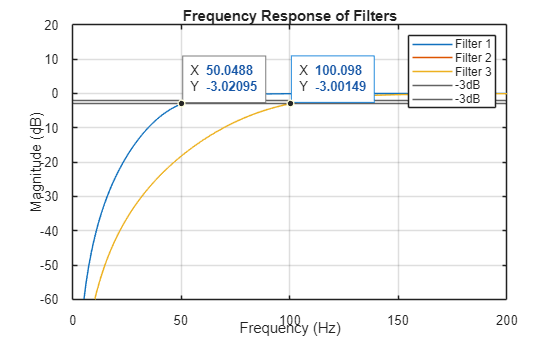


[h1, f1] = freqz(b_1, a_1, 1024, F_s);
[h2, f2] = freqz(b_2, a_2, 1024, F_s);
[h3, f3] = freqz(b_3, a_3, 1024, F_s);

% Plot the frequency response of the filters
figure;
plot(f1, 20*log10(abs(h1)), 'DisplayName', 'Filter 1');
hold on;
plot(f2, 20*log10(abs(h2)), 'DisplayName', 'Filter 2');
plot(f3, 20*log10(abs(h3)), 'DisplayName', 'Filter 3');
yline([-3 -2], 'DisplayName', '-3dB');
hold off;
xlim([0 200]);
ylim([-60 20]);
 
Filter1Line = findobj(gcf, "DisplayName", "Filter 1");
datatip(Filter1Line,50.05,-3.021);
Filter3Line = findobj(gcf, "DisplayName", "Filter 3");
datatip(Filter3Line,100.1,-3.001);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of Filters');
legend show;
grid on;

Ved -3dB er filter 1 ved 50Hz og filter 2 og 3 ved 100Hz.

Kravene er mindst -6dB ved 50Hz, og max -2dB ved 150Hz. Ved at se på grafen så ses det at filter 2 og 3 opfylder kravene.

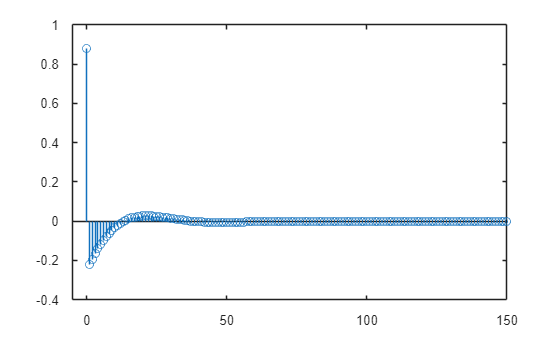

x = zeros(1, 1024);

x(1) = [1];

n = 0:1023;

y1 = filter(b_1, a_1, x);
y2 = filter(b_2, a_2, x);
y3 = filter(b_3, a_3, x);

figure;
stem(n, y1)
xlim([-5 150]);

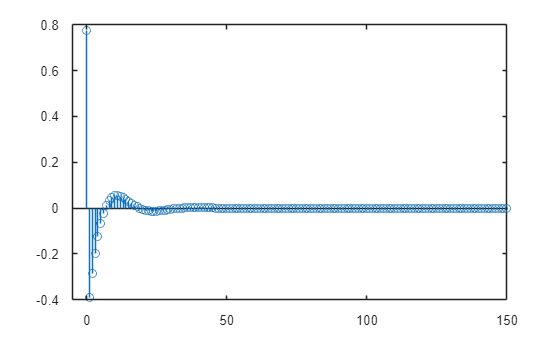

figure;
stem(n, y2)
xlim([-5 150])

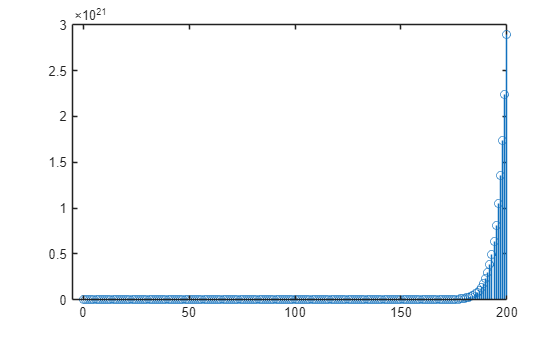


figure;
stem(n, y3)
xlim([-5 200])

Der ses, at filter 3 explodere ud til uendeligt, mens filter 1 og 2 er stabile.

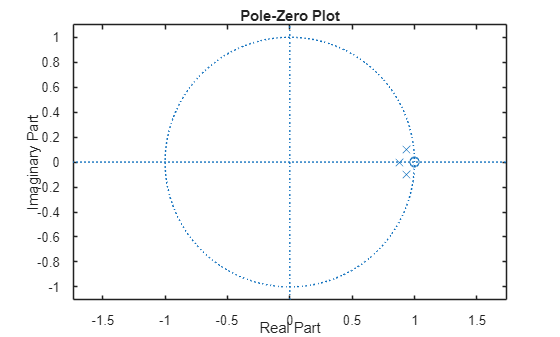

zplane(b_1, a_1)

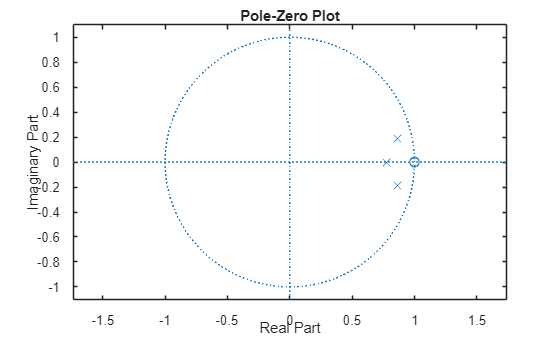

zplane(b_2, a_2)

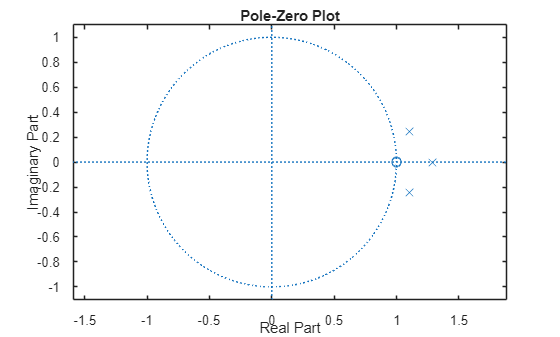

zplane(b_3, a_3)

zero-pole diagrammerne bekræfter, at siden polerne er udenfor enhedscirkelen for filter 3, er den ikke stabil i modsætning til filter 1 og 2.

Dvs. at filteret der opfylder kravspecifikkationerne og er stabil er filter 2.

clear; clc;
f_l = 250; f_h = 350; F_s = 2e3; N_taps = 25;

omega_l = (2*pi*f_l)/F_s

omega_l = 0.7854

omega_h = (2*pi*f_h)/F_s

omega_h = 1.0996


syms K M
M_value = double(solve(N_taps == M + 1));
K_value = double(solve(N_taps == 2*K + 1));

n = -K_value:K_value;

h = -(omega_h/pi)*sinc(n*omega_h/pi)+(omega_l/pi)*sinc(n*omega_l/pi);
h(K_value+1) = (pi-omega_h+omega_l)/pi; %VERY IMPORTANT -> K_VALUE + 1 FOR CENTER OF IMPUSLE RESPONSE

h(12)

ans = -0.0585

h(16)

ans = 0.0916

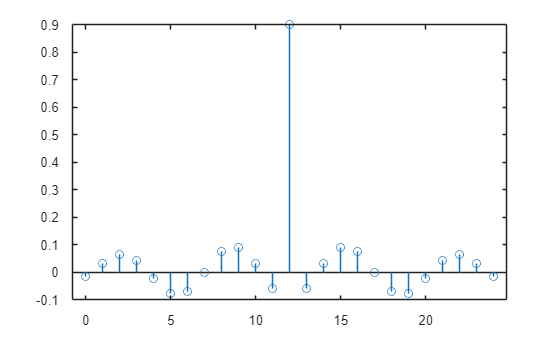


figure;
stem(0:M_value, h);

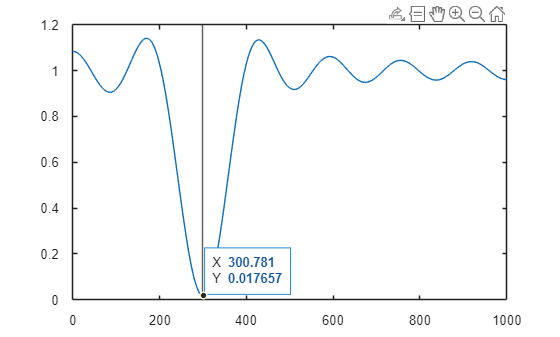

[H, f] = freqz(h, 1, 1024, F_s);

figure;
plot(f, abs(H));
xline([300]);

H(300Hz) = 0.88

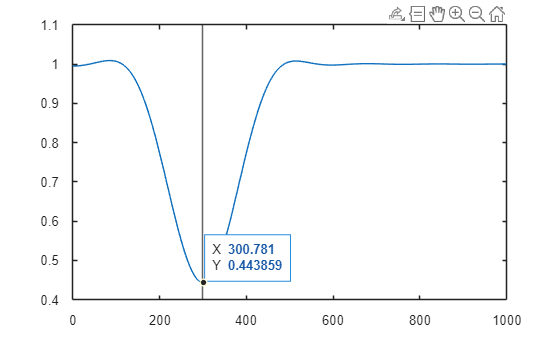

w_hanning = 0.5-0.5*cos(2*pi.*(0:M_value)/M_value);

h_hanning = h .* w_hanning;

[H_w, f] = freqz(h_hanning, 1, 1024, F_s);

figure;
plot(f, abs(H_w));
xline([300]);